addpath('resources', 'scripts');
clear

## Question 1

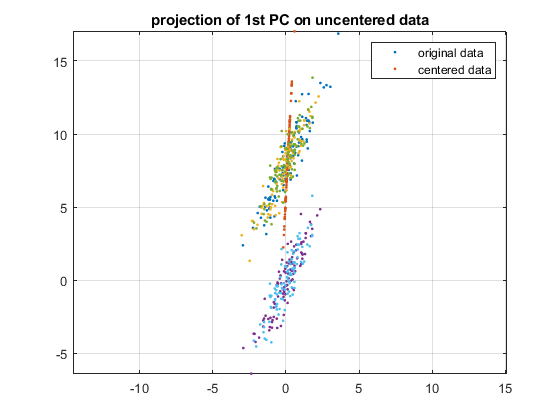

% build bi-variate time series X=[x1;x2] of 100 observations:
c1 = [2 8];
x1 = randn(1,100);
x2 = polyval(c1,x1)+randn(size(x1));
X = [x1;x2];

% CENTERING:
[m, n] = size(X);
mx = mean(X,2);
Xo = X - mx*ones(1, n);

% plot original and centered data:
plot(X(1,:),X(2,:),'.')
hold on
plot(Xo(1,:),Xo(2,:),'.')
grid on 
legend('original data', 'centered data')

## Question 2

**Rx: **correlation matrix, eig(Rx) = [U,D] (eigenvalue decomposition)

**D: **diagonal matrix collecting eigenvalues of Rx

**U: **orthogonal matrix, columns = corresponding eigenvectors

% eigenvalue decomposition:
N = length(Xo);
Rx = Xo*Xo'/(N-1); % correlation matrix
[U, D] = eig(Rx);

% proof of orthogonality of U:
isIdentityMatrix = transpose(U)*U

isIdentityMatrix =     1.0000         0
         0    1.0000


U*U' % equals? ->

ans =     1.0000         0
         0    1.0000


U'*U

ans =     1.0000         0
         0    1.0000



% note: D organizes eigenvalues in increasing order 
% standard definition: reorganize!
D = fliplr(flipud(D));
U = fliplr(U);

## Question 3

**EVD: X = A*Z**

**Z: **matrix of principal components

**A:** collecting corresponding eigenvectors

% convention: useless though
%A = U*D^(1/2); 
%Z = D^(-1/2)*U'*Xo;
% instead use:
A = U; 
Z = U'*Xo;
% Z*Z'/(N-1) is identity matrix?

## Question 4

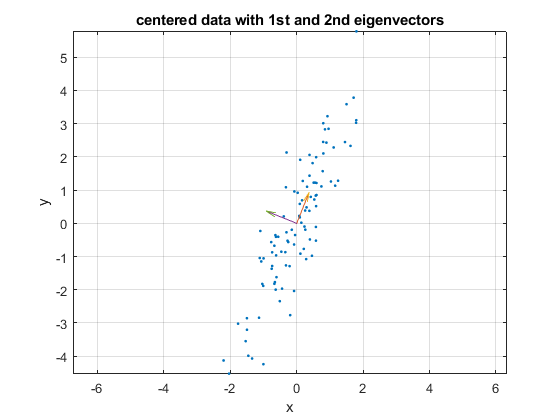

% Figure 2:
figure,
plot(Xo(1,:),Xo(2,:),'.')
grid on
hold on
vectarrow([0 0],A(:,1)')
hold on
vectarrow([0 0],A(:,2)')
axis equal
title('centered data with 1st and 2nd eigenvectors')

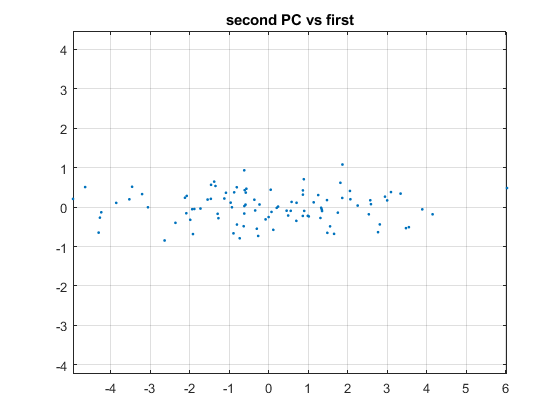


figure,
plot(Z(1,:),Z(2,:),'.')
grid on
axis equal
title('second PC vs first')

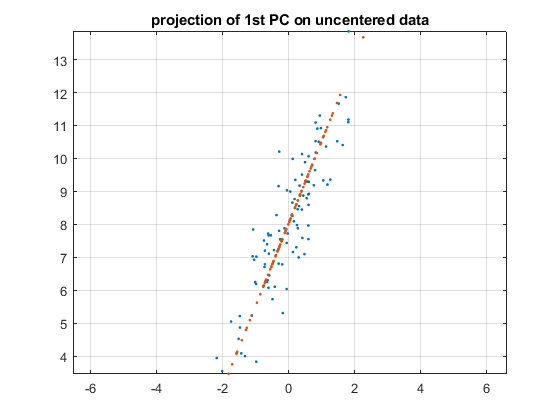


% projection of first PC on uncentered data
figure,
X1 = A(:,1)*pinv(A(:,1))*Xo+mx*ones(1,n);
plot(X(1,:),X(2,:),'.')
hold on
plot(X1(1,:),X1(2,:),'.')
grid on
axis equal
title('projection of 1st PC on uncentered data')



% don't see a clear direction in z1 
% would see if followed hypotheses:
% A^TA = AA^T = I, R_Z = D, A = U, Z = U^TX
% X^(1)o = A^(1)(A^(1)^T A^(1))^(-1) A^(1)^T Xo = A^(1) A^(1)^# Xo
% (A^(1)^T A^(1))^(-1) A^(1)^T = A^(1)^# (Pseudo inverse)
% assumption in literature: R_Z = I (EVD) PCs have same variances 
% (info about variances is in transformed matrix A = UD^(1/2))
% -> thats what we see in vectors, vectors have lengths proportional to variancs of next PC
% if standard definition is followed, vectors have same length and are spread along z1

% variation 2 (standard approach):
% A = U;
% Z = U'*Xo;
% Z*Z'/(N-1) is eigenvalues

Question 5: Repeat exercises 2 to 4, but this time without centering the data with respect to their mean values. Try to explain the main di�erences which can be noticed in each �gure.

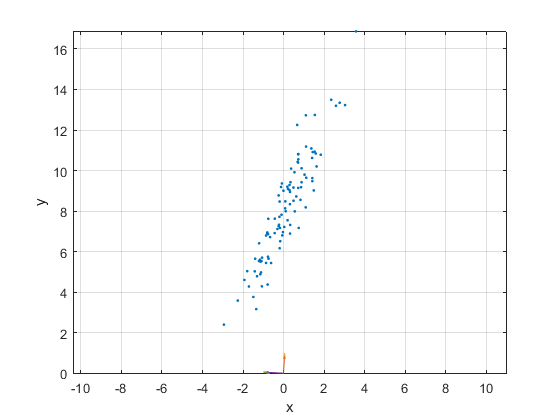

% Question 5

clear Rx U D Z A

Rx = X*X'/(N-1) ;
[U, D] = eig(Rx);
D = fliplr(flipud(D));
U = fliplr(U);
A = U;
Z = U'*X;

figure,
plot(X(1,:),X(2,:),'.')
grid on
hold on
vectarrow([0,0],A(:,1)')
hold on
vectarrow([0,0],A(:,2)')
axis equal

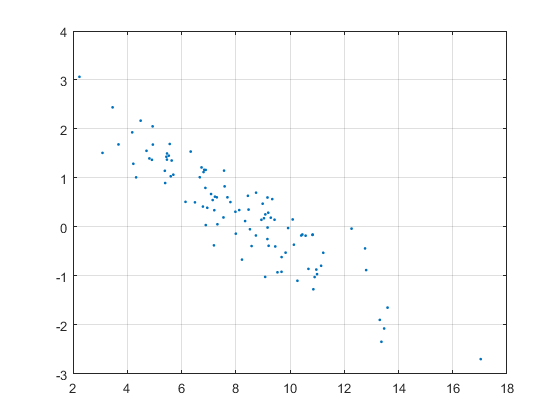


figure,
plot(Z(1,:),Z(2,:),'.')
grid on

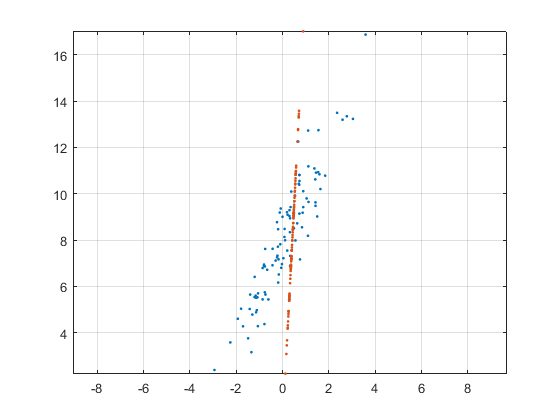


X1 = A(:,1)*pinv(A(:,1))*X;
figure,
plot(X(1,:),X(2,:),'.')
hold on
plot(X1(1,:),X1(2,:),'.')
grid on
axis equal

% Question 6
clear
load('data5.mat')
data = data'

data =     3.9964    3.9985    3.9998    4.0005    4.0005    4.0002    3.9997    3.9993    3.9989    3.9988    3.9988    3.9991    3.9998    3.9974    3.9949    3.9924    3.9901    3.9880    3.9860    3.9843    3.9827    3.9813    3.9800    3.9787    3.9775    3.9763    3.9751    3.9738    3.9725    3.9712    3.9699    3.9688    3.9677    3.9668    3.9661    3.9657    3.9656    3.9657    3.9662    3.9670    3.9680    3.9692    3.9706    3.9720    3.9735    3.9750    3.9763    3.9775    3.9784    3.9791
   -0.0278   -0.0187   -0.0105   -0.0041    0.0002    0.0020    0.0014   -0.0015   -0.0062   -0.0120   -0.0183   -0.0242   -0.0133   -0.0142   -0.0153   -0.0166   -0.0180   -0.0194   -0.0208   -0.0221   -0.0232   -0.0242   -0.0250   -0.0256   -0.0259   -0.0260   -0.0259   -0.0255   -0.0250   -0.0244   -0.0237   -0.0229   -0.0220   -0.0212   -0.0205   -0.0198   -0.0194   -0.0190   -0.0189   -0.0190   -0.0193   -0.0198   -0.0205   -0.0214   -0.0225   -0.0238   -0.0251   -0.0266   -0.0281  

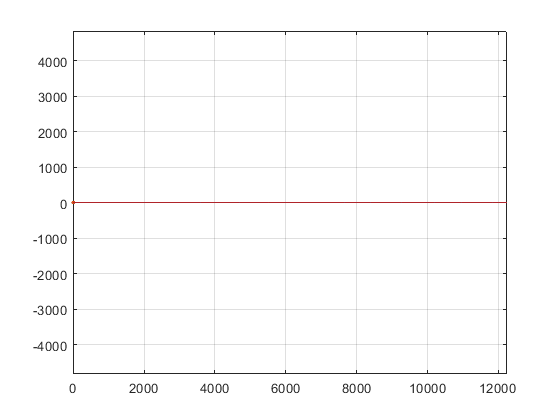

plot(data)

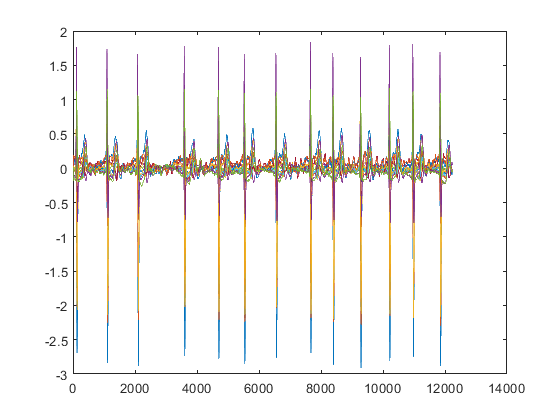


[m,n] = size(data);
mx = mean(data')';
data_centered = data - mx*ones(1,n);

figure,
plot(data_centered')

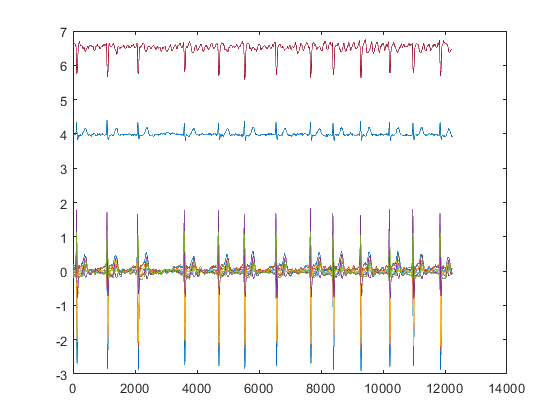


%------------------------
[U,S,V] = svd(data,'econ');

X = U*S*V';
[p,N] = size(X);

A = (U*S)/sqrt(N-1);
Z = sqrt(N-1)*V';

plot(data')